dt = 0.01; %time between 2 consecutive measurements
t = 0:dt:5;
T = 20e-3; %Interrogation time,
temperature = 4e-6 %Kelvin

temperature = 4.0000e-06

lambda = 500e-9 %wavelength of raman light

lambda = 5.0000e-07

y0 = 1; %Offset (difference between the measured true value of the senser)
sigma_y0 = 3e-3 % Standard deviation of y0

sigma_y0 = 0.0030

C = 0.2; %Contrast 
sigma_C = 4.5e-3 %S.D of C

sigma_C = 0.0045

du = randn*0.3; %detection Noise
phi_Laser = 0; %laser phase
phi_Acc = 0; %true inertial phase
phi_b = 12; %bias phase related to accelerometer
sigma_phi = 56e-3 % S.D of bias phase

sigma_phi = 0.0560

dphi_b = 30; %derivative of bias phase
sigma_phi_prime = 0.1 % S.D of derivative of bias phase

sigma_phi_prime = 0.1000


%The mechanical accelerometer suffers from bias (ab) and high frequency
%noise (da).
S_acc = (4*pi/lambda)*T^2; %Scale factor from the AI output, phiB = Sacc * ab

%a full fringe of the accelerometer corresponds to 100 micro g

dpsi = 0 %errors due to accelerometer noise, nonlinearity & finite bandwidth

dpsi = 0


%y is the output of the AI system after the final raman laser pulse
%y = y0 - (C/2)*cos(phi_Laser + phi_Acc) + du


x = [phi_b; dphi_b; y0; C]; %4 parameter state vector

F = [1 dt 0 0;
    0 1 0 0;
    0 0 1 0;
    0 0 0 1]; %Evolution matrix 

Q =  10e-3*[0 0 0 0;
    0 sigma_phi_prime^2 0 0;
    0 0 sigma_y0^2 0;
    0 0 0 sigma_C^2]; % Covariance matrix

w = dt*[sigma_phi*randn; sigma_phi_prime*randn; sigma_y0*randn; sigma_C*randn]; %Normally distributed  random
%variables with mean 0 and S.D sigma_j*dt 

%Variables change over time by the following:
%X(t+dt) = F * x(t) + w;

P = zeros(4);
R = 0.01*eye(4)

R =     0.0100         0         0         0
         0    0.0100         0         0
         0         0    0.0100         0
         0         0         0    0.0100


%Measurement values (simulated data)
phiB_measured = 0.2*sin(t) + randn(size(t))

phiB_measured =     1.4527    1.1992    0.2049   -1.7763   -0.7124    0.0612    1.3311   -1.0081   -1.0752   -0.1525   -0.8852   -0.8087   -0.2942   -0.1125   -0.2034    0.4297   -0.2119   -0.4000   -0.9134    0.2252   -0.9805    0.2827   -1.1518    0.7299    0.1312    1.4465    1.0608   -0.7483    0.4206    0.8936   -1.0904   -1.7710    0.9734   -0.2726    1.4068   -1.6145   -0.5147    1.5455   -0.6305   -2.6984   -1.2659   -0.8207    1.1303    0.1024    0.7589    0.2240   -0.1206    0.9738   -1.5024    1.3043


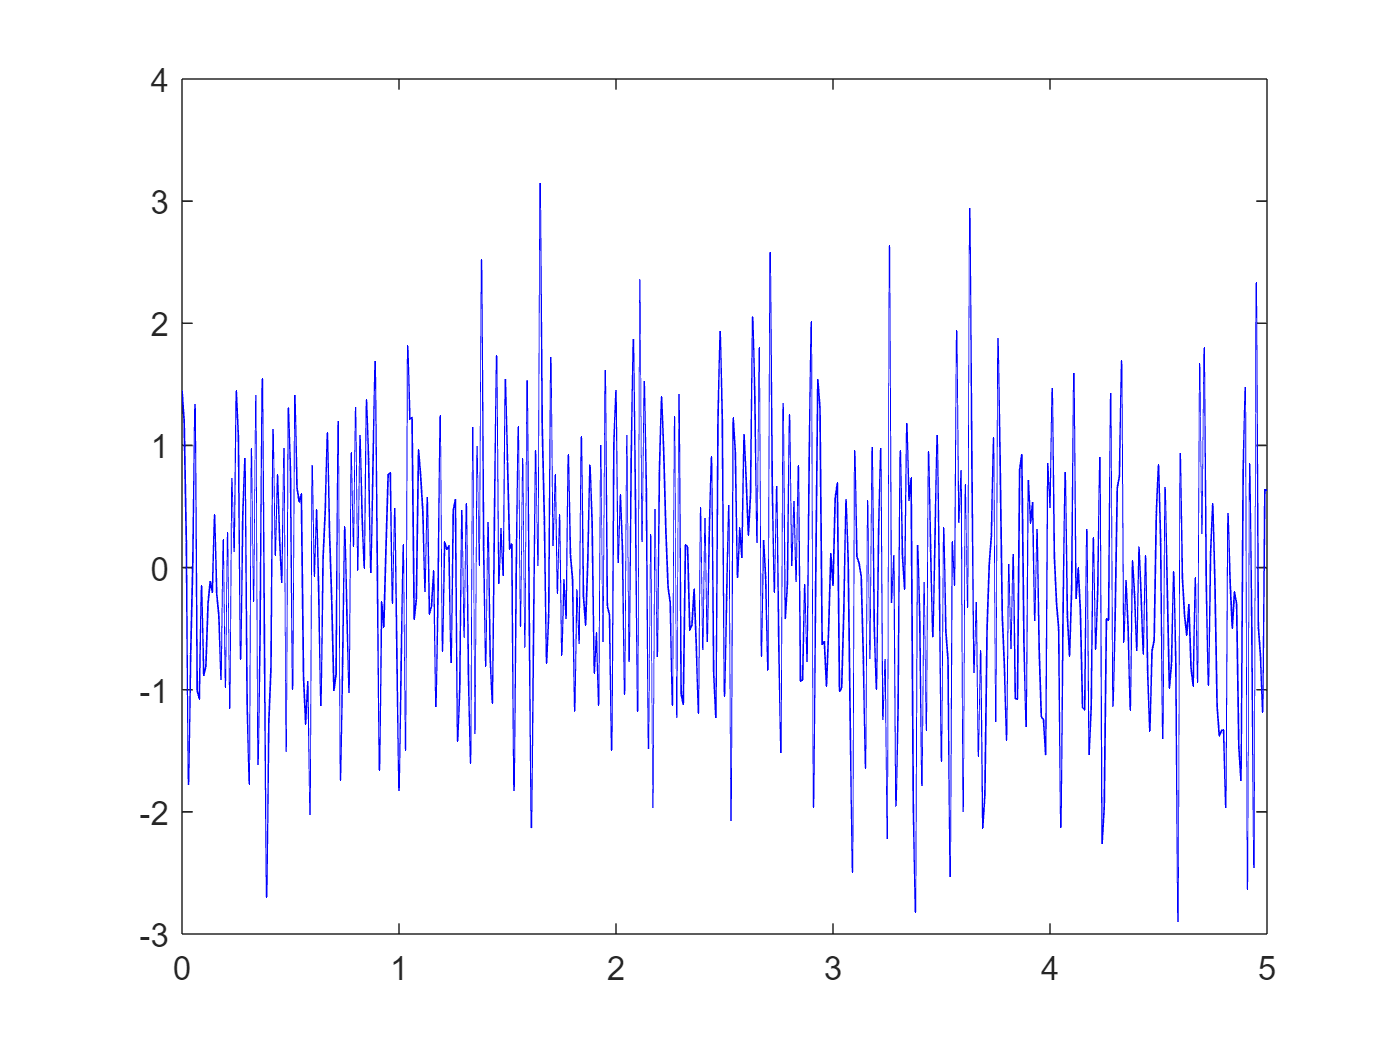

figure;
plot(t, phiB_measured, 'b'); hold off;

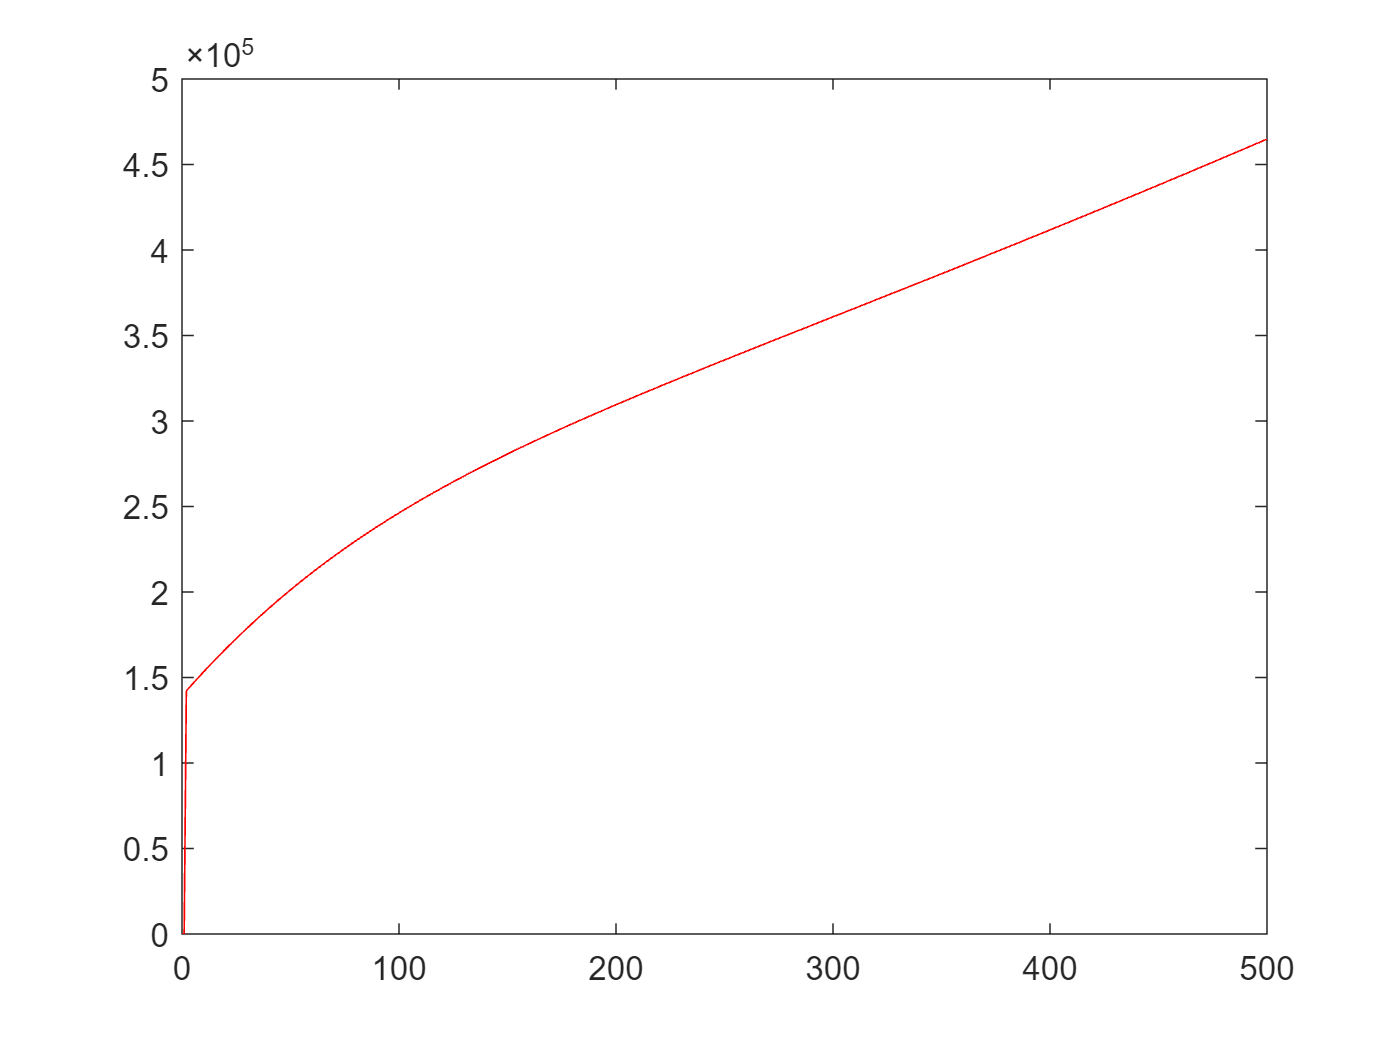

dphiB_measured = abs(40*sin(4*pi*t)+30*sin(7*pi*t)) + w(2,:);
y0_measured = abs(sin(3*pi*t)) + w(3,:);
C_measured = (0.2+abs(0.2*sin(15*pi*t))) + w(4,:);
K = [0 0 0 0];
xhat = zeros(4, length(t));
%Kalman Algorithm
for i=1:length(t)
    x_minus = F * x + dt*[sigma_phi*randn; sigma_phi_prime*randn; sigma_y0*randn; sigma_C*randn];
    P_minus = F*P*F' + Q;
    
    [yi,Hi] = yandH(y0_measured(i), C_measured(i), phiB_measured(i), phi_Laser, phi_Acc, du, dpsi);
    [yminus,Hminus] = yandH(x_minus(3), x_minus(4), x_minus(1), phi_Laser, phi_Acc, du, dpsi);
    r = yi - yminus; % innovation
    
    x = x_minus + K'*r;
    P = (eye(4) - K*Hi')*P_minus;
    K = P*Hi' \ (Hi*P*Hi' + R);
    xhat(:,i) = x;
end

figure;
plot(t*100, xhat(1,:), 'r'); hold off;

function [y,H] = yandH(y0, C, phiB, phi_Laser, phi_Acc, du, dpsi)
    y = y0 - (C/2)*cos(phi_Laser  + phi_Acc) + du;
    phi_acc_tilda = phi_Acc + phiB + dpsi;
    H = [(C/2)*sin(phi_acc_tilda  - phiB), 0, 1, -(1/2)*cos(phi_acc_tilda - phiB)];

end
